# Resolución de expresiones y ecuaciones

Existen diferentes funciones para la resolución de expresiones y ecuaciones tanto para encontrar raíces, respuestas numéricas, sistemas lineales y no lineales, etc.

Sin embargo, en este capítulo la función que destacará será `solve`.

## Función `solve`

Cuando se utiliza la función `solve`, el resultado (escalar o vector) es también simbólico. Por ende, antes de utilizar la salida se debe convertir a dato numérico mediante alguna función de esta clase de datos (`double`, `single`, `int8`, etc.).

### Para expresiones con una variable

Cuando se usa con una expresión, la función `solve` iguala la expresión a cero y resuelve para las raíces.

clear
syms x a b c z

f(x, a, b, c) = a*x^2 + b*x + c

$$f(x, a, b, c) = a\,x^{2}+b\,x+c$$

f(1, 1, b, z)

$$ans = b+z+1$$

solve(f, x)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

### Para expresiones con múltiples variables

La función `solve` es particularmente útil con expresiones simbólicas con múltiples variables, puesto que nos permite ingresar como segundo argumento la variable respecto a la cual se quiere resolver.

f(x, a, b, c) = a*x^2 + b*x == -c

$$f(x, a, b, c) = a\,x^{2}+b\,x=-c$$

f(1, 1, 1, 2)

$$ans = 2=-2$$

solve(f, x)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

Como se puede observar, la función `solve` ha despejado la variable **t** de la ecuación original.

### Para ecuaciones

También es posible determinar las raíces de una ecuación directamente.

% Su código va aquí :)

## Resolución de sistemas de ecuaciones

Para resolver un sistema de ecuaciones con la función `solve` basta con definir las ecuaciones e ingresarlas en la función.

syms y
eq1 = 3*x + 2*y == -1
eq2 = -2*x - 6*y == 9
S = solve(eq1, eq2)
A = [3  2
    -2 -6];

$$eq1 = 3\,x+2\,y=-1$$

b = [-1 9]';

$$eq2 = -2\,x-6\,y=9$$

A\b

S = struct with fields:
    x: 6/7
    y: -25/14


syms z a b c
eq1 = b*x*z == 10
eq2 = a*x*y - z== 5
eq3 = b*z*x + c*y == 100

ans =     0.8571
   -1.7857


eq = [eq1
      eq2
      eq3];

$$eq1 = b\,x\,z=10$$

[xS, yS, zS] = solve(eq, [x y z])

$$eq2 = a\,x\,y-z=5$$

Las respuestas son devueltas en una estructura.

% Su código va aquí :)

$$eq3 = c\,y+b\,x\,z=100$$

Pero estas soluciones son simbólicas, por ende, se deben convertir a numéricas para poder trabajar con estas.

S.x
S.y
S.z

Aunque si se quiere, directamente se puede igualar las soluciones a un arreglo salida.

% Su código va aquí :)

$$xS = \left(\begin{array}{c} \frac{5\,c+c\,\left(\frac{5\,\sqrt{\frac{144\,a+b\,c}{b\,c}}}{2}-\frac{5}{2}\right)}{90\,a}\\ \frac{5\,c-c\,\left(\frac{5\,\sqrt{\frac{144\,a+b\,c}{b\,c}}}{2}+\frac{5}{2}\right)}{90\,a} \end{array}\right)$$

$$yS = \left(\begin{array}{c} \frac{90}{c}\\ \frac{90}{c} \end{array}\right)$$

$$zS = \left(\begin{array}{c} \frac{5\,\sqrt{\frac{144\,a+b\,c}{b\,c}}}{2}-\frac{5}{2}\\ -\frac{5\,\sqrt{\frac{144\,a+b\,c}{b\,c}}}{2}-\frac{5}{2} \end{array}\right)$$

No obstante, las respuestas siguen siendo simbólicas.

**Nota:** Los resultados se asignan alfabéticamente. Por ejemplo, si las variables que se usaron en las expresiones son **q**, **x** y **p**, los resultados se regresarán en el orden **p**, **q**, **x**, independientemente de los nombres que se hayan asignado para los resultados.

### Sistemas de ecuaciones con función `solve` VS. solución matricial

Recordemos que para resolver un sistema de ecuaciones se vio en capítulos anteriores que es posible utilizar la matriz inversa de la matriz de coeficientes (aunque no se recomieda) y también con la división izquierda (esta sí se recomienda).

Ahora vemos que con la función `solve` también es posible solucionar un sistema de ecuaciones. Sin embargo, ¿cuál es la diferencia entre un método y otro? Pues bien:

- Resolver un sistema de ecuaciones matricialmente es más eficiente que utilizar la función `solve`.

- Pero un sistema de ecuaciones matricial debe ser lineal, esa es su limitación.

- No obstante, un sistema de ecuaciones no lineal se puede solucionar con la función `solve`.

## Tabla resumen del uso de la función `solve`

A continuación, se muestran algunas aplicaciones de la función `solve`.

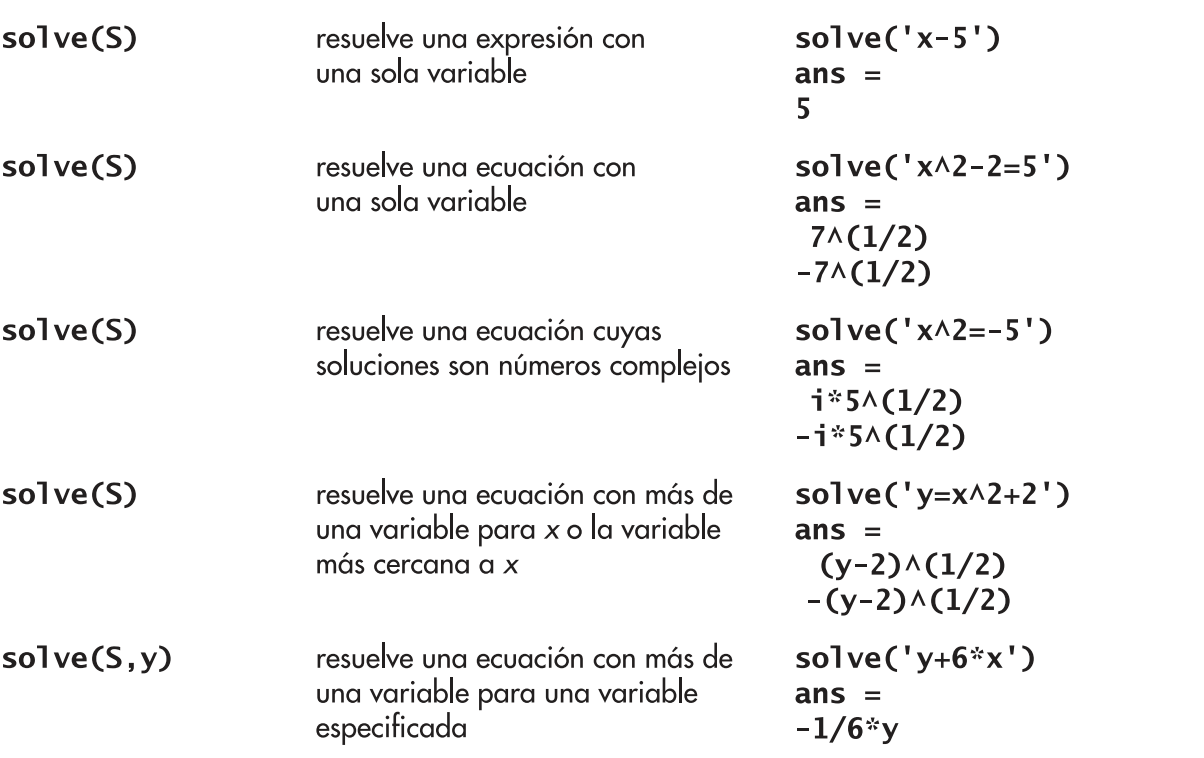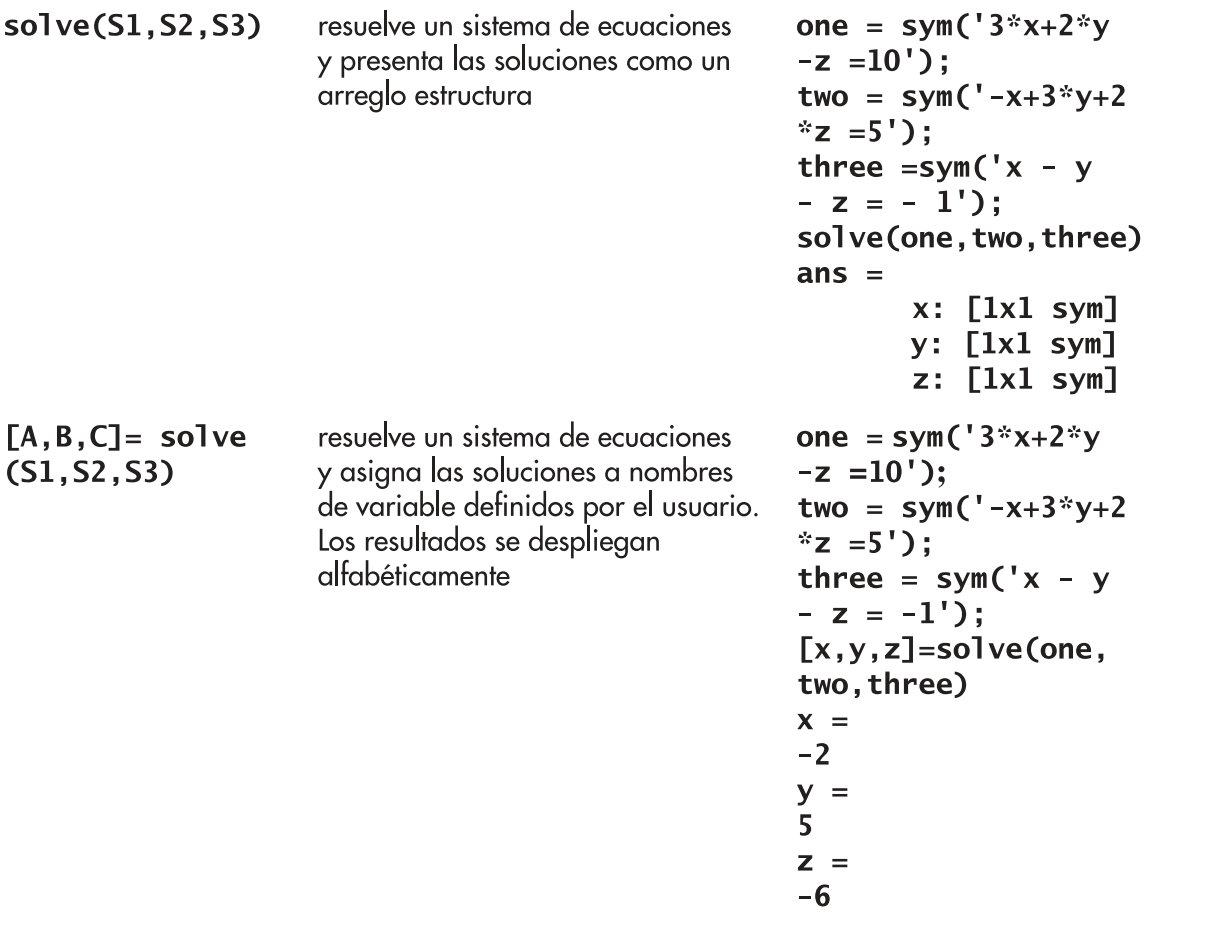

## Sustitución/evaluación de expresiones

También resulta útil renombrar variables o evaluarlas. Para esto sirve la función `subs`.

### Renombrar variables

Para renombrar variables se deben ingresar la expresión, la anterior variable y la nueva variable en la función `subs`. 

clear

$$ans = \begin{array}{l} \left(\begin{array}{c} -\frac{b\,c\,{\mathrm{root}\left(\sigma_{1},z_{1},1\right)}^{2}+5\,b\,c\,\mathrm{root}\left(\sigma_{1},z_{1},1\right)-1000\,a}{100\,a}\\ -\frac{b\,c\,{\mathrm{root}\left(\sigma_{1},z_{1},2\right)}^{2}+5\,b\,c\,\mathrm{root}\left(\sigma_{1},z_{1},2\right)-1000\,a}{100\,a}\\ -\frac{b\,c\,{\mathrm{root}\left(\sigma_{1},z_{1},3\right)}^{2}+5\,b\,c\,\mathrm{root}\left(\sigma_{1},z_{1},3\right)-1000\,a}{100\,a} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={z_{1}}^{3}+5\,{z_{1}}^{2}-\frac{1000\,a\,z_{1}}{b\,c}+\frac{1000\,a}{b^{2}\,c} \end{array}$$

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{b\,{\mathrm{root}\left(\sigma_{1},z_{1},1\right)}^{2}+5\,b\,\mathrm{root}\left(\sigma_{1},z_{1},1\right)}{10\,a}\\ \frac{b\,{\mathrm{root}\left(\sigma_{1},z_{1},2\right)}^{2}+5\,b\,\mathrm{root}\left(\sigma_{1},z_{1},2\right)}{10\,a}\\ \frac{b\,{\mathrm{root}\left(\sigma_{1},z_{1},3\right)}^{2}+5\,b\,\mathrm{root}\left(\sigma_{1},z_{1},3\right)}{10\,a} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={z_{1}}^{3}+5\,{z_{1}}^{2}-\frac{1000\,a\,z_{1}}{b\,c}+\frac{1000\,a}{b^{2}\,c} \end{array}$$

eq = str2sym('a*x^2 + b*x + c')

$$ans = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z_{1},1\right)\\ \mathrm{root}\left(\sigma_{1},z_{1},2\right)\\ \mathrm{root}\left(\sigma_{1},z_{1},3\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={z_{1}}^{3}+5\,{z_{1}}^{2}-\frac{1000\,a\,z_{1}}{b\,c}+\frac{1000\,a}{b^{2}\,c} \end{array}$$

subs(eq,'x','y')

En este caso hemos cambiado la variable simbólica **x** por la variable simbólica **y**.

**Nota:** Si las variables simbólicas se las ha definido previamente no es necesario ingresarlas entre apóstrofes.

### Evaluar una expresión

Siguiendo la misma estructura para renombrar variables se puede evaluarlas, en este caso el último parámetro es el valor donde se quiere evaluar.

subs(eq,'x', 2)

No obstante, también se puede evaluar múltiples variables simbólicas.

EQ = subs(eq, {'a','b','c'}, {9,2,3})

A su vez, también se puede evaluar varios valores.

numbers = (1:5)'
subs(EQ,'x',numbers)

$$eq = a\,x^{2}+b\,x+c$$

$$ans = a\,y^{2}+b\,y+c$$

$$ans = 4\,a+2\,b+c$$

$$EQ = 9\,x^{2}+2\,x+3$$

numbers =      1
     2
     3
     4
     5


$$ans = \left(\begin{array}{c} 14\\ 43\\ 90\\ 155\\ 238 \end{array}\right)$$